clear;clc;clf;
% Data from 5/30/2023 - Forresti
format short g ; format compact 
folder_path = "/Users/nbonnie/Desktop/FF_Stereo_Calibration_Free/";
fnames = dir(strcat(folder_path,"*.mat"))

fnames = 2×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum

addpath(genpath(folder_path))
data1 = load(strcat(folder_path, fnames(1).name));
data2 = load(strcat(folder_path, fnames(2).name));
fns1 = fieldnames(data1);
fns2 = fieldnames(data2);

df1 = data1.(fns1{1}).xyt;
df2 = data2.(fns2{1}).xyt;
c1n = data1.(fns1{1}).n;
c2n = data2.(fns2{1}).n;

% TIME SYNC & CHOP
% Q: Should time sync be automated / inferred?
% 
%
chop_tolerance = 1000; %frames

% CHOP START
c1_start = 3384;
c2_start = 2862;

% This next bit will update the indexes of the dataset that start first
% to match the slower indexes. All times will be index synced after this
if c1_start > c2_start
    df2(:,3) = df2(:,3) + (c1_start - c2_start);
elseif c2_start > c1_start
    df1(:,3) = df1(:,3) + (c2_start - c1_start);
else
    disp("Times are synced") % Times are synced
end

% Align to common start by removing indexes that start before the common
% start.
% (:, 3) is the time col of .xyt
df1(df1(:,3) <= (max(c1_start, c2_start) + chop_tolerance),:) = [];
df2(df2(:,3) <= (max(c1_start, c2_start) + chop_tolerance),:) = [];
% Reindex time to one (not zero since this is Matlab indexing at 1)
df1(:,3) = df1(:,3) - min(df1(:,3)) + 1;
df2(:,3) = df2(:,3) - min(df2(:,3)) + 1;
% Find chop length
chop_length = min(max(df1(:,3)), max(df2(:,3))) - chop_tolerance;

% CHOP END
df1(df1(:,3) > (chop_length),:) = [];
df2(df2(:,3) > (chop_length),:) = [];

% c1n & c2n need to start 2 indexes earlier. End is complicated

% CHOP N FRAMES
c1n = c1n((c1_start + chop_tolerance + 1):(c1_start + chop_tolerance + chop_length + 1));
c2n = c2n((c2_start + chop_tolerance + 1):(c2_start + chop_tolerance + chop_length + 1));
% Limit to actual data available
c1n((max(df1(:,3)) - min(df1(:,3)) + 1):end) = []; % Fencepost cuts
c2n((max(df2(:,3)) - min(df2(:,3)) + 1):end) = [];

max_time_interation = min(max(df1(:,3)),max(df2(:,3)));

%
% At this point, both df1 and df2 should be time synchonized by the df(:,3)
% column- aligning all x/y points with a similar df(t,3) value. Since
% different cameras will observe different points in a stereo environment,
% max(df1(:,3)) might not equal max(df2(:,3)) since these columns are not
% evaluating pure time, but recording occurances of flashing.
% Theoretically, c1n / c2n arrays should be evaluating time in a strictly
% linear non-repeating fashion.
%

% Everything should be checked with max(df1(:,3)) - 1 == size(c1n,2) && max(df2(:,3)) - 1 == size(c2n,2)

% Also manually verify with:
% disp(c1n(1:10))
% disp(size(df1(find(df1(:,3) == 1), :)))
% disp(size(df1(find(df1(:,3) == 2), :)))

% if the sizes match the numbers from c1n, everything is index matched
% meaning we can now search for density in c1n, and then pull the values
% with dfX(find(dfX(:,3) == <cXn index>), :)

% Grab all frames with 1 flash, grab xyt for C1 / C2

% Pre-allocate matrix
pairs = zeros((min(size(c1n,2), size(c2n,2))),6);
matrix_row_index = 1;
% For all indexes that exist in both datasets
for i = 1:(min(size(c1n,2), size(c2n,2)))
    if (c1n(i) == 1 && c2n(i) == 1)  % If the .n of each index == 1, pull xyt
        % If there is only 1 flash in both frames, pull xyt from both dfs
        pairs(matrix_row_index,:) = [df1(df1(:,3) == i, :), df2(df2(:,3) == i, :)];
        matrix_row_index = matrix_row_index + 1;
    end
end
pairs = pairs(1:(matrix_row_index-1),:); % Trim out unused allocation

% Pin all points from C1 at 0,0 - plot all C2 displatement relative to C1
displacements = zeros(size(pairs,1),2);
for i = 1:size(pairs,1)
    % X2 - X1, Y2 - Y1
    displacements(i,:) = [pairs(i,5)-pairs(i,2), pairs(i,4)-pairs(i,1)];
end

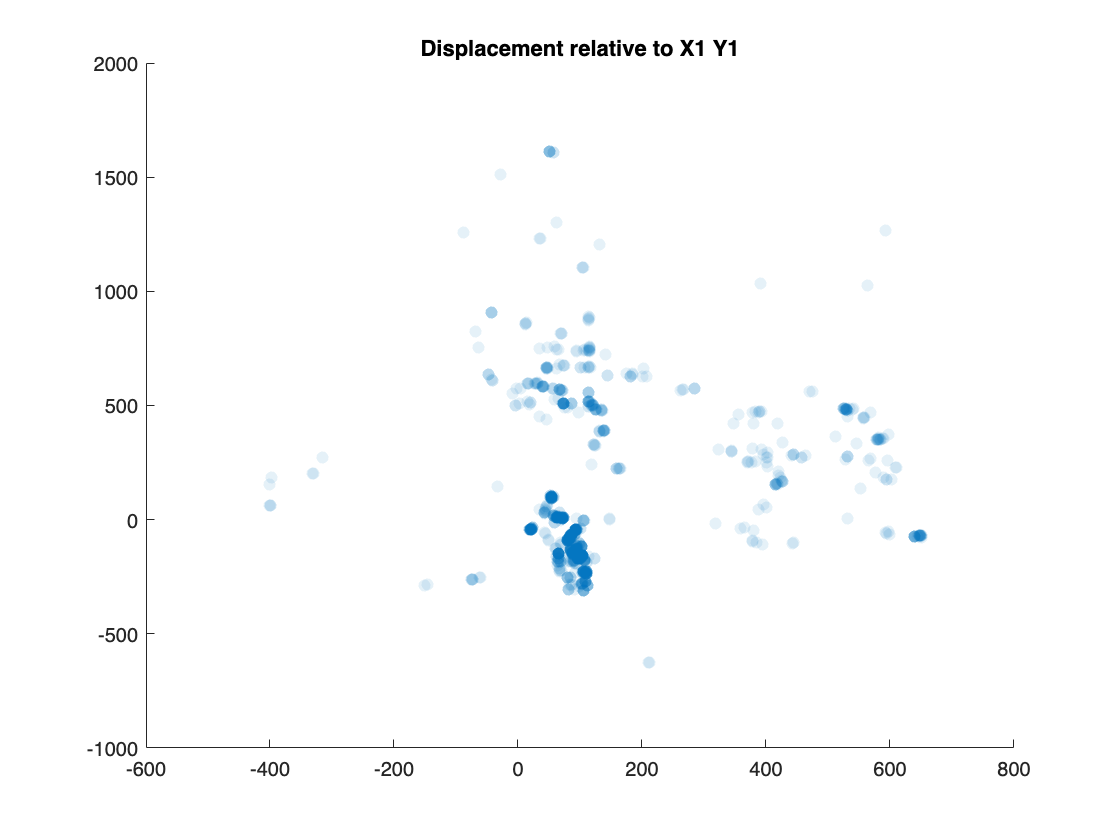

% 2D distribution analysis of C2 displacement
s = scatter(displacements(:,1), displacements(:,2), "filled");
title("Displacement relative to X1 Y1")
s.MarkerFaceAlpha = 0.1;

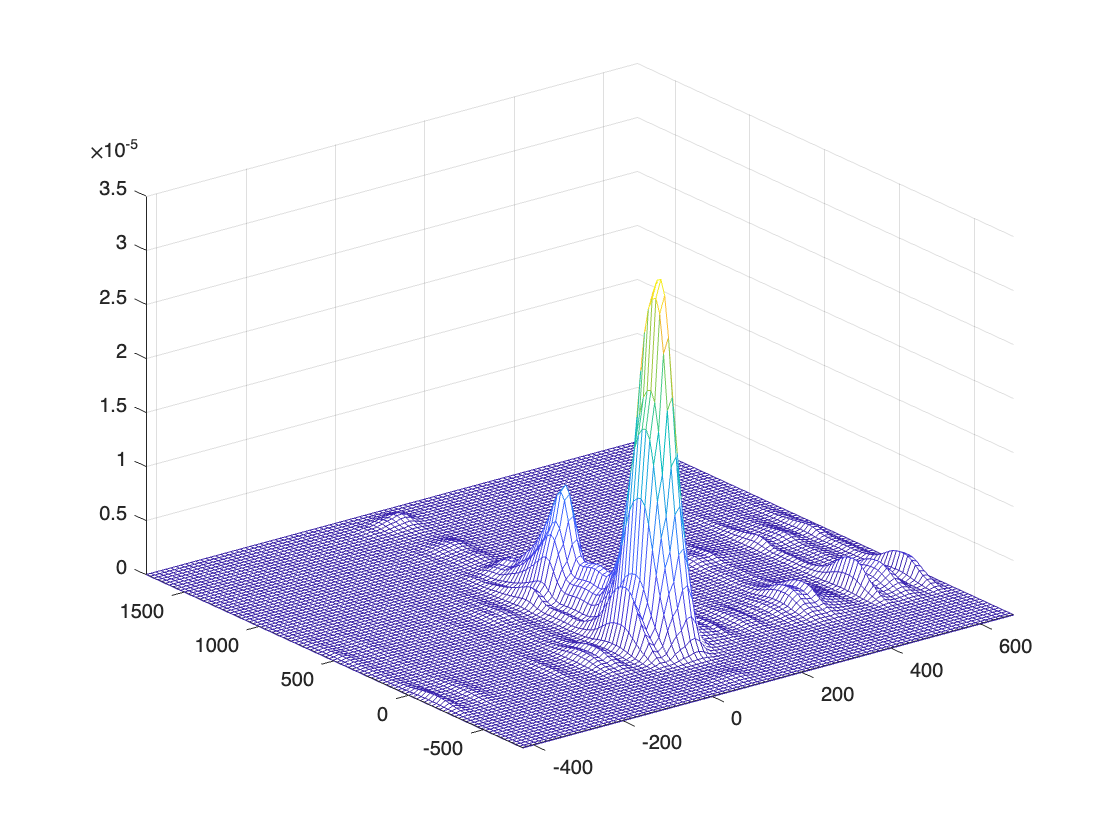

% Construct pdf for X & Y vars, plot

% Estimate a continuous pdf from the discrete data
[pdfx, xi]= ksdensity(displacements(:,1));
[pdfy, yi]= ksdensity(displacements(:,2));
% Create 2-d grid of coordinates and function values, suitable for 3-d plotting
[xxi,yyi]     = meshgrid(xi,yi);
[pdfxx,pdfyy] = meshgrid(pdfx,pdfy);
% Calculate combined pdf, under assumption of independence
pdfxy = pdfxx.*pdfyy; 
% Plot the results
mesh(xxi,yyi,pdfxy)
set(gca,'XLim',[min(xi) max(xi)])
set(gca,'YLim',[min(yi) max(yi)])

[Zmax,Idx] = max(pdfxy(:));
fprintf("Max:   x: %.2f   y: %.2f\n",xxi(Idx), yyi(Idx))

Max:   x: 97.46   y: -129.04


% Toss outliers, keep all points within threshold
% we have the expected displacement values-  keep all points within a
% certain range.
% Evaluate all pairs (not just single pairs) and if they meet a boolean
% displacement criteria, keep the points

% Determine translation matrix that maps C1 -> C2

% Apply translation to all points to determine genuine match points within
% threshold

% Reconstruct in 3d? 